# ACO Assignment 2022 Q3 H Infinity Controller

## Load Linearized State-space plant

clc 
clear 
load linearizedModel_Outputs.mat


## Define some variables for use

s = zpk('s') %for defining transfer functions

s =
 
  s
 
Continuous-time zero/pole/gain model.



om_rad = logspace(-2,5,1001); %define logspace range for plotting bode plot
om_rad_lin = linspace(0.5,3,1001); %define range for plotting highlight of frequency range

bw_gamma_rad = 0.2*2*pi %define target azimuth motion bandwith, 2pi radians is one hertz

bw_gamma_rad = 1.2566

bw_alpha_rad = 0.25*2*pi %define target elevation motion bandwith, 2pi radians is one hertz

bw_alpha_rad = 1.5708

##  Look at the plant

% figure(1)
% bode(P_ss_self, om_rad)
% grid on


## Singular Value

% figure(2)
% subplot(1,2,1)
% sigma(P_ss_self,om_rad)
% legend
% grid on
% subplot(1,2,2)
% sigma(P_ss_self,om_rad_lin)
% legend
% grid on

% rng(0,'twister'); % For reproducibility
% H = rss(4,2,3);
% bode(H)
% grid on
% sigma(H)
% legend
% grid on

## Design the weights individually then combine them

%Penalize high frequency input from the actuator
W_Vgamma = 1;%same importance, no bandwidth limit for control signal, yet
W_Valpha = 1;%same importance

Wi =mdiag(W_Vgamma,W_Valpha);
Wi = ss(Wi);

Wo11 = 35e-2/(s + 8*bw_gamma_rad);%1*bw_gamma_rad
Wo22 = 62e-2/(s + 8*bw_alpha_rad); %0.1*bw_alpha_rad
Wo = mdiag(Wo11,Wo22);
Wo = ss(Wo);


## Form the Weighted Plant

P_ss_self

P_ss_self =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1           0           1           0           0           0           0
   x2           0          -1  -6.847e-12           0   5.689e+04           0
   x3           0           0           0           1           0           0
   x4           0           0           0          -1           0    5.73e+04
   x5           0           0           0           0       -1000           0
   x6           0           0           0           0           0       -1000
 
  B = 
       u1  u2
   x1   0   0
   x2   0   0
   x3   0   0
   x4   0   0
   x5   1   0
   x6   0   1
 
  C = 
       x1  x2  x3  x4  x5  x6
   y1   1   0   0   0   0   0
   y2   0   0   1   0   0   0
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



Pw = Wo*P_ss_self*Wi

Pw =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1      -10.05           0         0.5           0           0           0
   x2           0      -12.57           0           0           1           0
   x3           0           0           0           1           0           0
   x4           0           0           0          -1  -6.847e-12           0
   x5           0           0           0           0           0           1
   x6           0           0           0           0           0          -1
   x7           0           0           0           0           0           0
   x8           0           0           0           0           0           0
 
               x7          x8
   x1           0           0
   x2           0           0
   x3           0           0
   x4   5.689e+04           0
   x5           0           0
   x6           0    5.73e+04
   x7       -1000           0
   x8           0       -1000
 
  B = 
   

## Check the weighted plant with sigma

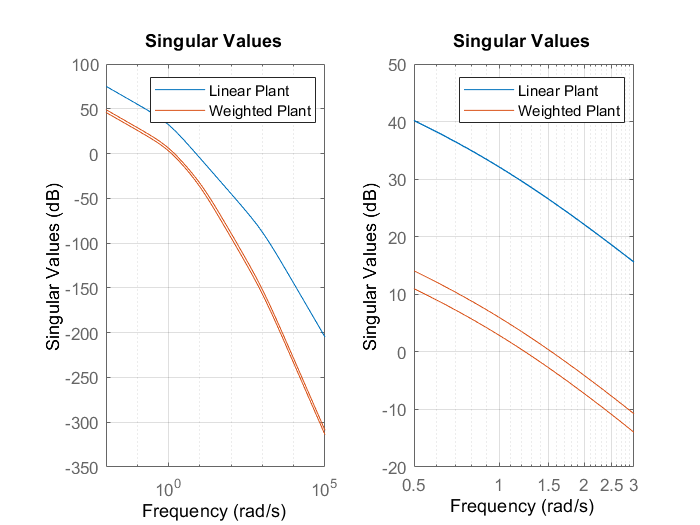

figure(3)
clf
subplot(1,2,1)
sigma(P_ss_self,Pw,om_rad)
legend ('Linear Plant', 'Weighted Plant')
grid on
subplot(1,2,2)
sigma(P_ss_self,Pw,om_rad_lin)
legend ('Linear Plant', 'Weighted Plant')
grid on

## Check the weight plant with bode

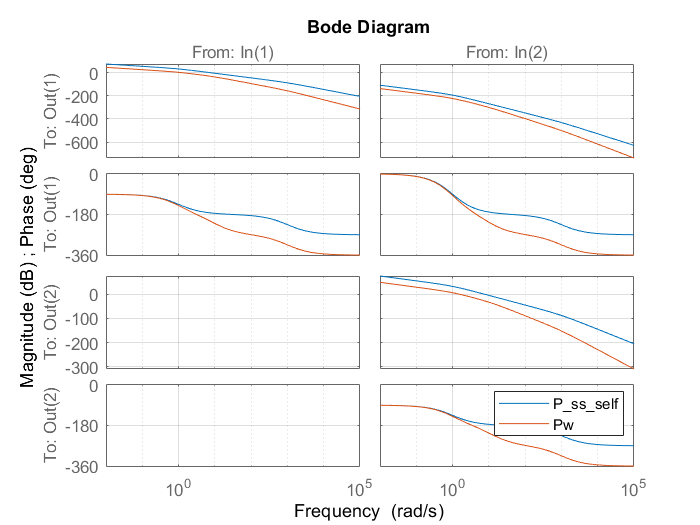

figure(4)
bode(P_ss_self,Pw,om_rad)

legend
grid on

## Check the robustness with rho, v-gap

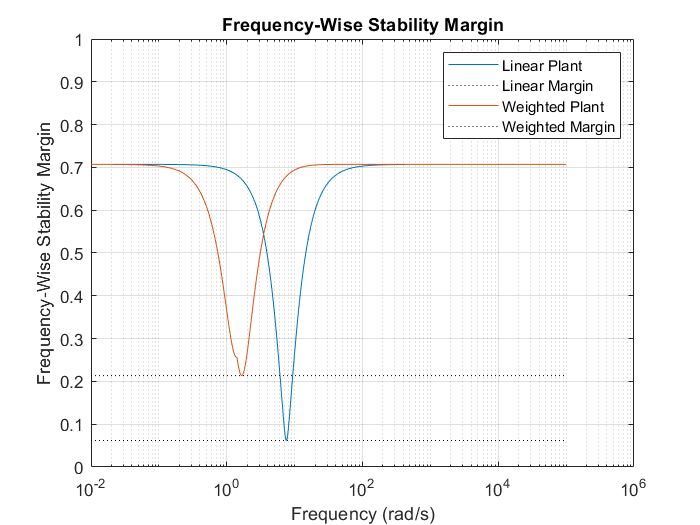

figure(5)
clf
rho(P_ss_self, -eye(2),om_rad)
hold on
rho(Pw, -eye(2),om_rad)
grid on
legend('Linear Plant','Linear Margin','Weighted Plant','Weighted Margin')
hold off

## Check robustness with multiloop input output diskmargin

[~,MM_P] = diskmargin(P_ss_self)

MM_P = struct with fields:
           GainMargin: [0.8832 1.1322]
          PhaseMargin: [-7.0982 7.0982]
           DiskMargin: 0.1240
           LowerBound: 0.1240
           UpperBound: 0.1243
            Frequency: 7.5556
    WorstPerturbation: [2×2 ss]


% DGM_P_alpha = DM_P(2).GainMargin;
% DGM_P_gamma = DM_P(1).GainMargin;

% DGMAll_P = [DGM_P_gamma;DGM_P_alpha];
DGM_P = MM_P.GainMargin;

[~,MM_Pw] = diskmargin(Pw)

MM_Pw = struct with fields:
           GainMargin: [0.6418 1.5580]
          PhaseMargin: [-24.6129 24.6129]
           DiskMargin: 0.4363
           LowerBound: 0.4363
           UpperBound: 0.4372
            Frequency: 1.6640
    WorstPerturbation: [2×2 ss]


% DGM_Pw_alpha = DM_Pw(2).GainMargin
% DGM_Pw_gamma = DM_Pw(1).GainMargin

% DGMAll_Pw = [DGM_Pw_gamma;DGM_Pw_alpha];
DGM_Pw = MM_Pw.GainMargin;

## Plot the diskmargins

figure(6)
clf
t6 = tiledlayout(1,2,'TileSpacing','None',"Padding","none");
ax6a = nexttile

ax6a =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.0367 0.0470 0.4817 0.9340]
            Units: 'normalized'

  Show all properties


diskmarginplot(DGM_P,'disk')

ax6b = nexttile

ax6b =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5191 0.0470 0.4659 0.9052]
            Units: 'normalized'

  Show all properties


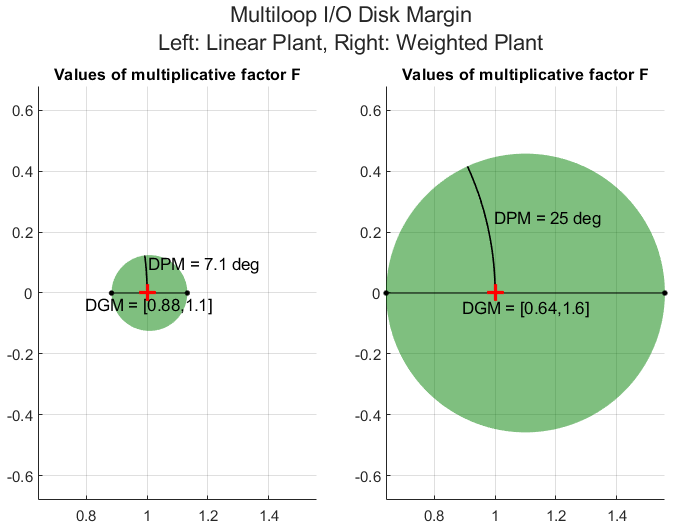

diskmarginplot(DGM_Pw,'disk')
linkaxes([ax6a,ax6b],'x')
linkaxes([ax6a,ax6b],'y')
% 
t6title = {'Multiloop I/O Disk Margin','Left: Linear Plant, Right: Weighted Plant'};
% 
% title(t6,{t6title})
title(t6,t6title)


%% 
% figure(7)
% clf
% t = tiledlayout(2,2,'TileSpacing','Compact');
% 
% nexttile
% diskmarginplot(DGM_P_gamma,'nyquist')
% nexttile
% diskmarginplot(DGM_P_alpha,'nyquist')
% nexttile
% diskmarginplot(DGM_Pw_gamma,'nyquist')
% nexttile
% diskmarginplot(DGM_Pw_alpha,'nyquist')
% title(t,{'Disk Margin for robustness within region of uncertainty','First Column: Azimuth Voltage to '})


## H-infinity Synthesis

## Form the controller

Pw

Pw =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1      -10.05           0         0.5           0           0           0
   x2           0      -12.57           0           0           1           0
   x3           0           0           0           1           0           0
   x4           0           0           0          -1  -6.847e-12           0
   x5           0           0           0           0           0           1
   x6           0           0           0           0           0          -1
   x7           0           0           0           0           0           0
   x8           0           0           0           0           0           0
 
               x7          x8
   x1           0           0
   x2           0           0
   x3           0           0
   x4   5.689e+04           0
   x5           0           0
   x6           0    5.73e+04
   x7       -1000           0
   x8           0       -1000
 
  B = 
   


Cinf =  -ncfsyn(Pw);
C = Wi * Cinf * Wo;
C = minreal(C)

C =
 
  A = 
                x1          x2          x3          x4          x5          x6
   x1       -11.27   8.824e-13         0.5           0           0           0
   x2    1.132e-12      -14.14           0           0           1           0
   x3       -26.02   2.306e-11           0           1           0           0
   x4        -13.8   6.071e-11           0          -1  -6.847e-12           0
   x5    1.407e-11      -20.98           0           0           0           1
   x6    -1.89e-12      -14.54           0           0           0          -1
   x7       -0.541   3.767e-09     -0.4752     -0.2439   5.047e-09   2.238e-09
   x8    5.042e-09      -193.3   4.342e-09   2.253e-09      -258.9      -114.8
   x9            0           0           0           0           0           0
   x10           0           0           0           0           0           0
 
                x7          x8          x9         x10
   x1            0           0        1.22  -8.824e-13
   x2 

zpk(C)

ans =
 
  From input 1 to output...
                                                                         
         8.196 (s+6570) (s+1000)^2 (s+11.74) (s+10.05) (s+4.658) (s+1.22)
                                                                         
   1:  ---------------------------------------------------------------------
                                                                            
       (s+1000)^2 (s+6570) (s+13.89) (s+11.74) (s+10.05) (s+4.658)          
                                                                            
                                                      (s^2 + 12.24s + 37.49)
                                                                            
 
                                                                                  
       -7.6938e-08 (s+1000)^2 (s+12.57) (s+10.06) (s+0.9036) (s^2 + 3.04s + 3.534)
                                                                                  
                             


L = P_ss_self*C

L =
 
  A = 
                x1          x2          x3          x4          x5          x6
   x1            0           1           0           0           0           0
   x2            0          -1  -6.847e-12           0   5.689e+04           0
   x3            0           0           0           1           0           0
   x4            0           0           0          -1           0    5.73e+04
   x5            0           0           0           0       -1000           0
   x6            0           0           0           0           0       -1000
   x7            0           0           0           0           0           0
   x8            0           0           0           0           0           0
   x9            0           0           0           0           0           0
   x10           0           0           0           0           0           0
   x11           0           0           0           0           0           0
   x12           0           0         

## Look at the close loop response

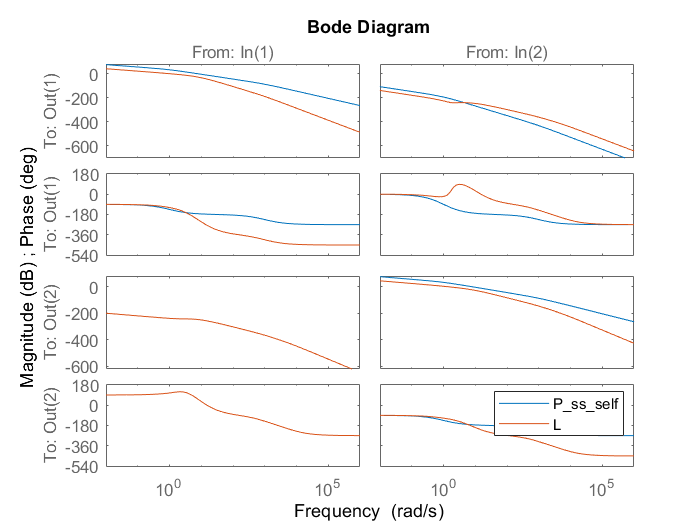

figure(8)
clf
bode(P_ss_self,L)
legend